# Data Analysis in Meteorology and Oceanography - Tutorial 1

# 海洋气象学数据分析基础 - 一讲

Content Creator : Li Hua

Content Reviewer: Reviewer 1

## Data 

In this tutorial we will use the NOAA OI Daily Mean SST V2 High Resolution Dataset for global Sea Surface Temperature (SST) in 2006. The data can be downloaded via [ftp://ftp2.psl.noaa.gov/Datasets/noaa.oisst.v2.highres/sst.day.mean.2006.nc.](ftp://ftp2.psl.noaa.gov/Datasets/noaa.oisst.v2.highres/sst.day.mean.2006.nc.)

## Set Your Path

Move to the folder where the data are stored, and run the following line in the command window.

pwd;

addpath(ans);

It will add the folder containing the data to search path, so that the data can be found by MATLAB even though you move to other folder.

Similarly, you can add any folder in your machine to your search path by simply replace `ans` with the path you want, e.g. `/Users/xxxx/Dropbox/streaming`.

## Display Your NetCDF Files

You can use MATLAB function `ncdisp` to display the information of your NetCDF files in your command window:

ncdisp('sst.day.mean.2006.nc')

Source:
           /Users/zijiezhao/Dropbox/streaming/sst.day.mean.2006.nc
Format:
           netcdf4_classic
Global Attributes:
           Conventions   = 'CF-1.5'
           title         = 'NOAA High-resolution Blended Analysis: Daily Values using AVHRR only'
           institution   = 'NOAA/NCDC'
           source        = 'NOAA/NCDC  ftp://eclipse.ncdc.noaa.gov/pub/OI-daily-v2/'
           comment       = 'Reynolds, et al., 2007: Daily High-Resolution-Blended Analyses for Sea Surface Temperature. J. Climate, 20, 5473-5496.  Climatology is based on 1971-2000 OI.v2 SST, Satellite data: Navy NOAA17 NOAA18 AVHRR, Ice data: NCEP ice.'
           history       = 'Thu Aug 24 13:47:53 2017: ncatted -O -a References,global,d,, sst.day.mean.2006.v2.nc
                           Version 1.0'
           dataset_title = 'NOAA Daily Optimum Interpolation Sea Surface Temperature'
           References    = 'https://www.psl.noaa.gov/data/gridded/data.noaa.oisst.v2.highres.html'
Dimensions:
      

Alternatively, you can use another style:

ncdisp sst.day.mean.2006.nc

Source:
           /Users/zijiezhao/Dropbox/streaming/sst.day.mean.2006.nc
Format:
           netcdf4_classic
Global Attributes:
           Conventions   = 'CF-1.5'
           title         = 'NOAA High-resolution Blended Analysis: Daily Values using AVHRR only'
           institution   = 'NOAA/NCDC'
           source        = 'NOAA/NCDC  ftp://eclipse.ncdc.noaa.gov/pub/OI-daily-v2/'
           comment       = 'Reynolds, et al., 2007: Daily High-Resolution-Blended Analyses for Sea Surface Temperature. J. Climate, 20, 5473-5496.  Climatology is based on 1971-2000 OI.v2 SST, Satellite data: Navy NOAA17 NOAA18 AVHRR, Ice data: NCEP ice.'
           history       = 'Thu Aug 24 13:47:53 2017: ncatted -O -a References,global,d,, sst.day.mean.2006.v2.nc
                           Version 1.0'
           dataset_title = 'NOAA Daily Optimum Interpolation Sea Surface Temperature'
           References    = 'https://www.psl.noaa.gov/data/gridded/data.noaa.oisst.v2.highres.html'
Dimensions:
      

It presents complete details of each variable in the NetCDF file.  Each variable is characterized by various attributes. We do not need to care all of them but some are important and worth noting, such as:

- `units` - Interpretation of Data.

- `valid_range` - Data points out of range may be unreasonable.

- `missing_value` - Absent data points are covered by missing value.

Attributes in each NetCDF file are independent as they are subjectively determined by NetCDF creators, so they can be different in various NetCDF files.

## Read Your NetCDF files

Run the following line in your command window can store the variable `sst` in file `sst.day.mean.2006.nc` as `sst_2006` in workspace.

clear % clear workspace
sst_2006=ncread('sst.day.mean.2006.nc','sst');
whos % display variables in workspace

  Name             Size                      Bytes  Class     Attributes

  sst_2006      1440x720x365            1513728000  single              



We can see the varible `sst` in the NetCDF file is stored as `sst_2006` in workspace. `sst` is a 3D variable in size of [1440 720 365], separately corresponding to longitude, latitude, and time (each day of year).

The following line read the variables longitude and latitude in the NetCDF file  and store them.

lon=ncread('sst.day.mean.2006.nc','lon');
lat=ncread('sst.day.mean.2006.nc','lat');
whos

  Name             Size                      Bytes  Class     Attributes

  lat            720x1                        2880  single              
  lon           1440x1                        5760  single              
  sst_2006      1440x720x365            1513728000  single              



We can see that the sizes of longitude and latitude are separately 1440 and 720. For longitude, we can simply visualize it to see its numerical representation.

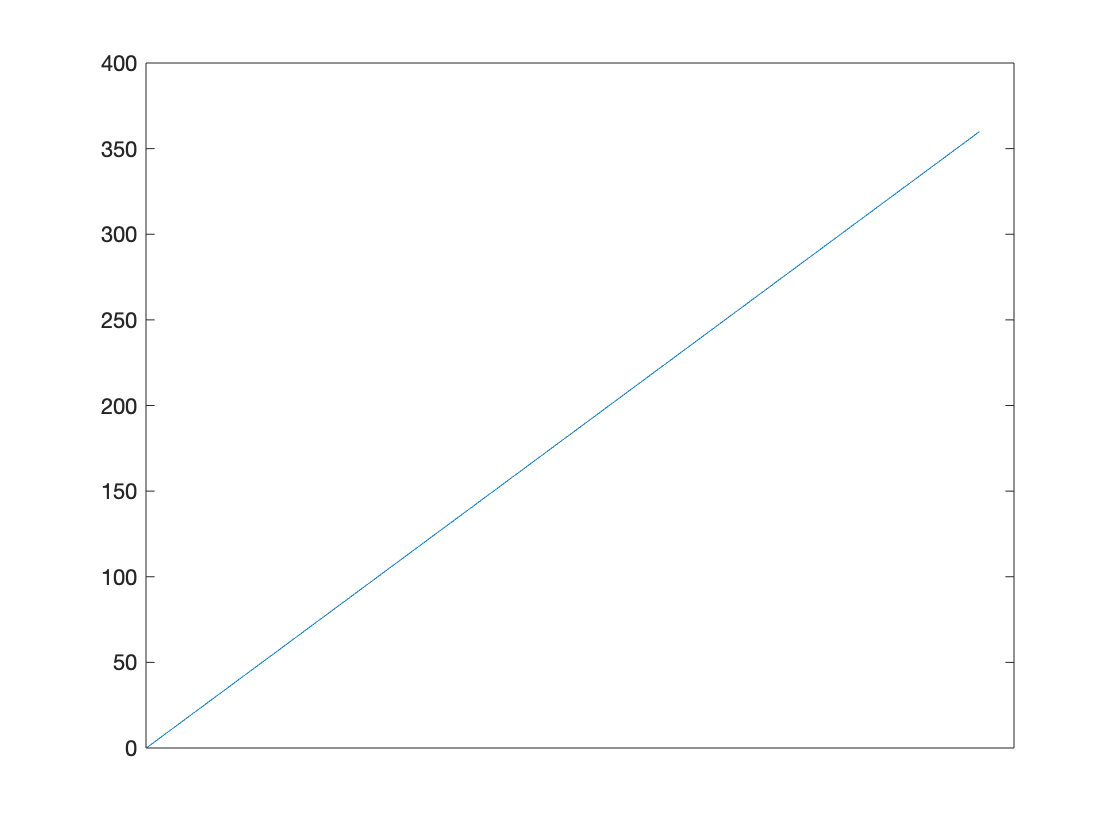

plot(lon);%very simple visualization
set(gca,'xtick',[]);

We can see the longitude varies from 0 to 360. It should be noted that 180 - 360 instead of -180 - 0 indicate west here, to ensure the continuity of longitude data.

Similarly, we can visualize latitude data.

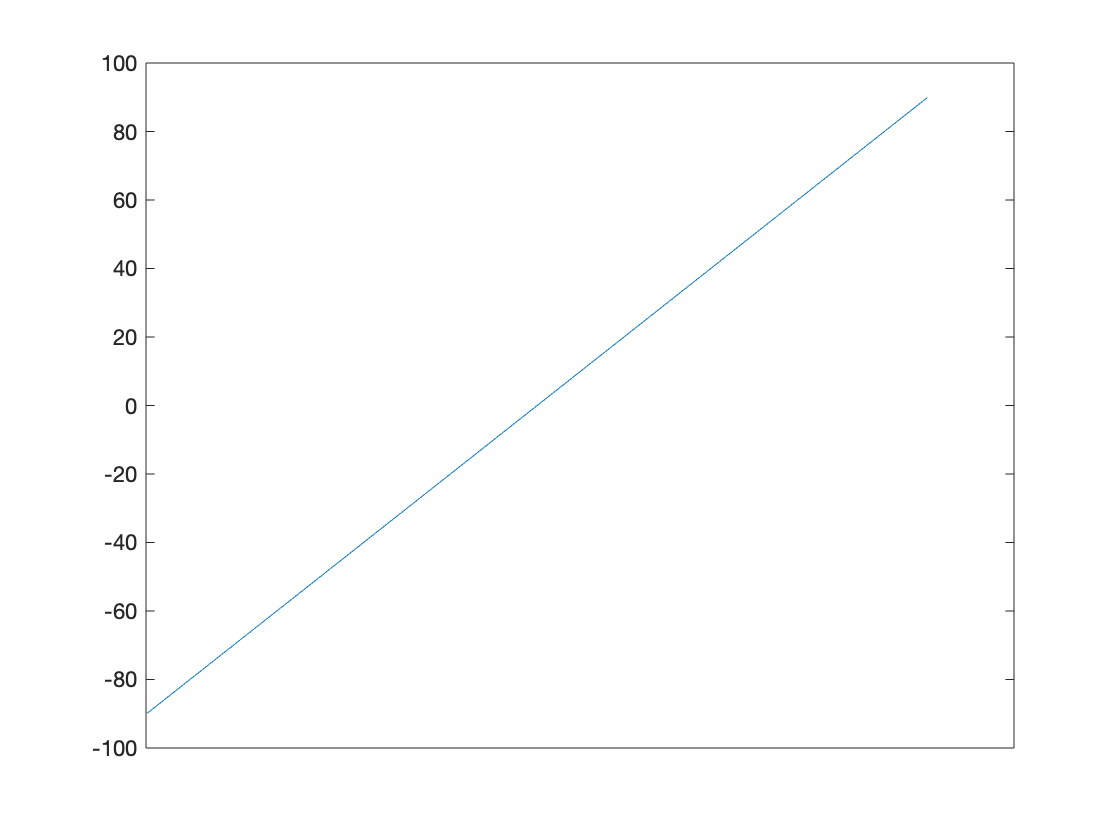

plot(lat);%very simple visualization
set(gca,'xtick',[]);

As what we may expected, it ranges from -90 to 90, with positive values indicate north and negative values indicate south.

## Read Your NetCDF files - SST at Particular Time Points

If we do not want to read the whole variable, but only a part of it, such as a particular time point instead of the whole 2006, how should we modify the code?

Running the following line in your command window can store the global SST in the second day of 2006 as `sst_2006_2`.

sst_2006_2=ncread('sst.day.mean.2006.nc','sst',[1 1 2],[inf inf 1]);
whos

  Name               Size                      Bytes  Class     Attributes

  lat              720x1                        2880  single              
  lon             1440x1                        5760  single              
  sst_2006        1440x720x365            1513728000  single              
  sst_2006_2      1440x720                   4147200  single              



This line is similar to the previous one but has two additional inputs. The 3rd input `[1 1 2] `indicates the starting location of reading for each dimension. The 4th input `[inf inf 1]` means the number of elements to read along each dimension, while `inf` here means all. Therefore, the whole line means reading the variable `sst` in the NetCDF file from the location `[1 1 2]` until the end of the first two dimensions and by 1 in the third dimension, and storing the output as `sst_2006_2`. 

We can easily modify the above line to read the global SST from the first day to the 31th day (i.e. the whole January):

% Read the sst in January of 2006.
sst_2006_jan=ncread('sst.day.mean.2006.nc','sst',[1 1 1],[inf inf 31]);

## Read Your NetCDF files - SST on Particular Dates

The idea to read the part of SST at a particular date is to first determine the location of it in the variable, and then read it using the abovementioned procedure.

Here we try to read the global SST on Feb 28th 2006. First determine the location of the date (Feb 28th 2006) in the time period of our data (whole 2006).

clear;
index=datenum(2006,2,28)-datenum(2006,1,1)+1;

This line calculates the location of Feb 28th in 2006. The function `datenum(year,month,day,...)` converts the input time point to the serial date number, which is the whole and fractional number of days  from date `Jan 0, 0000` in the proleptic ISO calendar. The location of targeted time point can hence be calculated as its "distance" from the starting time point.

After determining the location, we can read the data following the abovementioned procedure.

sst_2006_28Feb=ncread('sst.day.mean.2006.nc','sst',[1 1 index],[inf inf 1]);
whos

  Name                   Size               Bytes  Class     Attributes

  index                  1x1                    8  double              
  sst_2006_28Feb      1440x720            4147200  single              



Similarly, codes here can be easily modified to read data on a series of dates. The following line read the global SST in Feb 2006.

index=datenum(2006,2,1)-datenum(2006,1,1)+1;
sst_2006_Feb=ncread('sst.day.mean.2006.nc','sst',[1 1 index],[inf inf 28]);
whos

  Name                   Size                    Bytes  Class     Attributes

  index                  1x1                         8  double              
  sst_2006_28Feb      1440x720                 4147200  single              
  sst_2006_Feb        1440x720x28            116121600  single              



## Read Your NetCDF files - SST over a particular area.

In above section we show how to read data in NetCDF files temporally. However, sometimes we also want to specify the geographical location of data when reading it. In this section, we will show some examples about it.

The idea to read the data over a specific area is similar to the temporal read of data as what we have shown above, but here we need to consider the location of data points along two dimensions, which are separately longitude and latitude. The following lines show how to read the global SST in 2006 over the area 60 - 120 $^{o}$ E,  30 - 60 $^{o}$S.

clear;
% Read the longitude and latitude for further use
lon=ncread('sst.day.mean.2006.nc','lon');
lat=ncread('sst.day.mean.2006.nc','lat');
index_lon=find(lon<=120 & lon>=60);
index_lat=find(lat<=-30 & lat>=-60);
sst_lonlat=ncread('sst.day.mean.2006.nc','sst',[index_lon(1) index_lat(1) 1],[length(index_lon) length(index_lat) inf]);
% function `length` outputs the number of elements in an array
whos

  Name               Size                    Bytes  Class     Attributes

  index_lat        120x1                       960  double              
  index_lon        240x1                      1920  double              
  lat              720x1                      2880  single              
  lon             1440x1                      5760  single              
  sst_lonlat       240x120x365            42048000  single              



The input `lon<=120 & lon>=60` returns the logical representation of each data point, which is marked as 1 if yes and 0 otherwise. The function `find` returns a vector containing the linear indices of each nonzero element in the input array. Therefore, `find(lon<=120 & lon>=60)` returns the locations of elements in `lon` satisfying the specific longitude range. The same procedure can be easily adapted to latitude. Therefore, we can read the SST over the specific area from the starting location (`index_lon(1) `and `index_lat(1)`, the first elements of index_lon and index_lat separately) by the lengths of `length(index_lon)` and `length(index_lat)` separately.